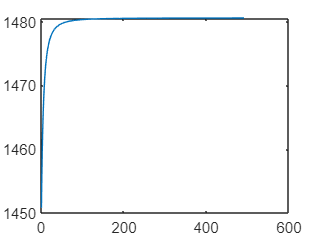

a = 0;
b = 30;

ns = 10:500;
sums = [];

for n = ns
    val = TRAPsolver(a, b, n);
    sums(n-9) = val;
end

plot(sums);

function [val] = TRAPsolver(a, b, n)
    delta_x = (b-a) / n;
    xl = linspace(a, b-delta_x, n);
    xr = linspace(a+delta_x, b, n);
    left = 200.*(xl./(5+xl)) .* exp(-2.*xl./30);
    right = 200.*(xr./(5+xr)) .* exp(-2.*xr./30);

    val = sum(((left+right)./2).*delta_x);
end